## Оценка параметров реального привода по данным из csv файла

### Читаем CSV файл

clear; clc;
% test_csv = readmatrix("sin_4_8.csv")
test_csv = readmatrix("sin_664.csv");
% test_csv = readmatrix("sin_664_acs712.csv")

% примерные параметры
% 1.9556
% 0.6153
% 1.9952
% 0.0087
% 0.0022

test_csv(2,2)

ans = 12182959

data_length = length(test_csv(:,2))-1

data_length = 704

time = test_csv(2:data_length+1, 2);    % мкс
ticks = test_csv(2:data_length+1, 3) / 15000 * 2 * pi;  % рад
input = test_csv(2:data_length+1, 4) / 100 * 12;    % В
current = test_csv(2:data_length+1, 5) / 1000;  % А
% current = test_csv(2:data_length+1, 5);  % А ACS712
current_orig = current;

t_start = time(1);
time = (time - t_start)/1000000;    % с

dticks = zeros(1, data_length);
dticks_orig = zeros(1, data_length);
dticks_smooth = zeros(1, data_length);

ddticks = zeros(1, data_length);
ddticks_orig = zeros(1, data_length);

dI = zeros(1, data_length);
dI_orig = zeros(1, data_length);

% no smooth works /7
% f_w = 1
% f_b = 0.1
% f_i = 1
% f_di = 0.05

% works for sin_664.csv
% f_w = 1
% f_b = 0.7
% f_i = 1
% f_di = 0.05

f_w = 1

f_w = 1

f_b = 0.7

f_b = 0.7000

f_i = 1

f_i = 1

f_di = 0.05

f_di = 0.0500


for k = 2:data_length
    dt = time(k)-time(k-1);

    dticks_orig(k) = ( ticks(k)-ticks(k-1) )/dt;
    ddticks_orig(k) = ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    dI_orig(k) = ( current(k)-current(k-1) )/dt;

%     dticks(n) = ( ticks(n)-ticks(n-1) )/dt;
    dticks(k) = dticks(k-1)*(1-f_w) + f_w * ( ticks(k)-ticks(k-1) )/dt;

%     ddticks(n) = ( dticks(n)-dticks(n-1) )/dt;
%     ddticks(n) = ddticks(n-1)*(1-f_b) + f_b * ( dticks(n)-dticks(n-1) )/dt;
    ddticks(k) = ddticks(k-1)*(1-f_b) + f_b * ( dticks_orig(k)-dticks_orig(k-1) )/dt;
    
%     current(n) = current(n-1)*(1-f_i) + f_i * current(n);

%     dI(n) = ( current(n)-current(n-1) )/dt;
    dI(k) = dI(k-1)*(1-f_di) + f_di * ( current(k)-current(k-1) )/dt;
end

dticks = smooth(dticks, 3);

% works for sin_664.csv
current = smooth(current, 3);
ddticks = smooth(ddticks, 12);
dI = smooth(dI, 5);

figure;
plot(time, ticks)
title("Angle")
xlim("auto")
ylim("auto")
grid on

plot(time, dticks_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

plot(time, dticks)
% hold
% plot(time, dticks_orig)
% hold 
title("W")
xlim("auto")
ylim("auto")
grid on

% plot(time_smooth, dticks_smooth)
% % plot(time, dticks_smooth)
% title("W smooth")
% xlim("auto")
% ylim("auto")
% grid on

plot(time, ddticks_orig)
title("B orig")
xlim("auto")
ylim("auto")
grid on

plot(time, ddticks)
title("B")
xlim("auto")
ylim("auto")
grid on

plot(time, current_orig)
title("I orig")
xlim("auto")
ylim("auto")
grid on

plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

plot(time, dI_orig)
title("dI orig")
xlim("auto")
ylim("auto")
grid on

title("dI")
plot(time, dI)
xlim("auto")
ylim("auto")
grid on

figure
title("U")
hold on
plot(time, input)
% plot(time, dticks)
hold off
xlim("auto")
ylim("auto")
grid on

### Kalman filter state estimation parameters

% from offline parameter identification
L = 1.9556;
R = 0.6153;
Kw = 1.9952;
Km = 1.9952;
J = 0.0087;
Lam = 0.0022;

%V2
% x = [q w dw I]'
% u = u
% A = [0       1        0        0;
%      0    -eLam/eJ      0      eKm/eJ;
%      0 -eKm*eKw/(eJ*eL) -eLam/eJ -eKm*eR/(eJ*eL);
%      0    -eKw/eL       0      -eR/eL]
% B = [0 0 eKm/(eJ*eL) 1/eL]'
% C = eye(4)
% % C_lqr = [1 0 0 0]
% Cq = 1;
% Cw = 0;
% Cdw = 0;
% Ci = 0;
% C_lqr = [Cq 0  0   0;  %q
%          0  Cw 0   0;  %w
%          0  0  Cdw 0;  %dw
%          0  0  0   Ci] %I
% D = [0 0 0 0]'

% V3
% x = [w dw I]'
% u = u
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A =    -0.2529         0  229.3333
 -233.9772   -0.2529  -72.1563
   -1.0202         0   -0.3146


inv(A)

ans =    -0.0013    0.0000   -0.9798
   -0.0000   -3.9545  906.9091
    0.0044    0.0000   -0.0011


B = [0 Km/(J*L) 1/L]'

B =          0
  117.2701
    0.5114


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = [0 0 0]'

D =      0
     0
     0



Vd_w = 100;
Vd_dw = 1;
Vd_I = 1e-2;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];
% Vn = 1
% Vn = [1 0;
%       0 1];
Vn = [1 0 0;
      0 1 0;
      0 0 1];

% C_lqe = [1 0 0]
% C_lqe = [1 0 0;
%          0 1 0];
C_lqe = [1 0 0;
         0 1 0;
         0 0 1];
% [Kf, Pf, Ef] = lqe(A, Vd, C_lqe, Vd, Vn);
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009);
Kf

Kf =     0.9555   -0.0308   -0.0001
   -0.0308    0.9706    0.0042
   -0.0001    0.0042    0.0001



[Te, De] = eig(A);
Cc = ctrb(A,B)

Cc = 1.0e+04 *

         0    0.0117   -0.0067
    0.0117   -0.0067   -2.7410
    0.0001   -0.0000   -0.0120


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001         0         0
         0    0.0001         0
         0         0    0.0001
   -0.0000         0    0.0229
   -0.0234   -0.0000   -0.0072
   -0.0001         0   -0.0000
   -0.0234         0   -0.0130
    0.0192    0.0000   -5.3618
    0.0001         0   -0.0234


rank(Cc)

ans = 2

rank(Cob)

ans = 3


% [Te, De] = eig(A)
% At = expm(A*dt)
% At = real(Te*expm(De*dt)*inv(Te))

% A_hat = A-Kf*C_lqe
% B_hat = [B Kf]
% D_hat = [D D]

### KF estimation on raw data

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0012 - 0.0652i  -0.0012 + 0.0652i
   1.0000 + 0.0000i   0.9979 + 0.0000i   0.9979 + 0.0000i
   0.0000 + 0.0000i   0.0043 - 0.0001i   0.0043 + 0.0001i


De =   -0.2529 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2838 +15.2963i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2838 -15.2963i


At = expm(A*dt)

At =     0.9883    0.0000    2.0531
   -2.0923    0.9977   -2.8123
   -0.0091   -0.0000    0.9877


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B

Bt =    0.0047 + 0.0000i
   1.0499 + 0.0000i
   0.0046 + 0.0000i


A_hat = (At-Kf*C_lqe)

A_hat =     0.0328    0.0308    2.0533
   -2.0615    0.0271   -2.8166
   -0.0090   -0.0042    0.9877


B_hat = [Bt Kf]

B_hat =    0.0047 + 0.0000i   0.9555 + 0.0000i  -0.0308 + 0.0000i  -0.0001 + 0.0000i
   1.0499 + 0.0000i  -0.0308 + 0.0000i   0.9706 + 0.0000i   0.0042 + 0.0000i
   0.0046 + 0.0000i  -0.0001 + 0.0000i   0.0042 + 0.0000i   0.0001 + 0.0000i



for k = 1:data_length-1
    u_act = input(k);
%     u = [u_act dticks(k)]';
    u = [u_act (C_lqe*[dticks(k) ddticks(k) current(k)]')']';
    x_arr(:, k+1) = A_hat*x_arr(:, k)+B_hat*u;
    dt = time(k+1)-time(k);
    q_arr(k+1) = q_arr(k) + x_arr(1, k)*dt;
end

% x_arr_d2 = x_arr;
% t_d2 = t;
% t = linspace(ts, tf, num_of_steps);

figure
hold on
plot(time, ticks)
plot(time, q_arr)

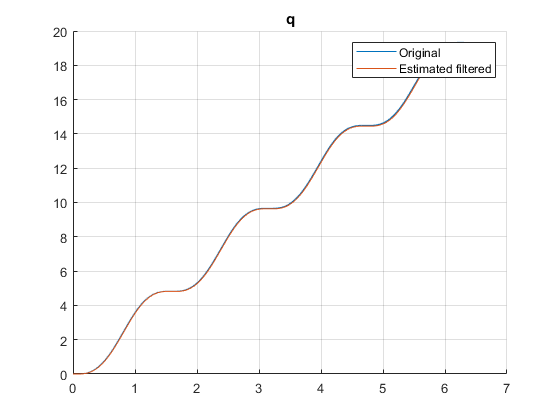

hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")


figure
hold on
plot(time, dticks_orig)
plot(time, x_arr(1, :))

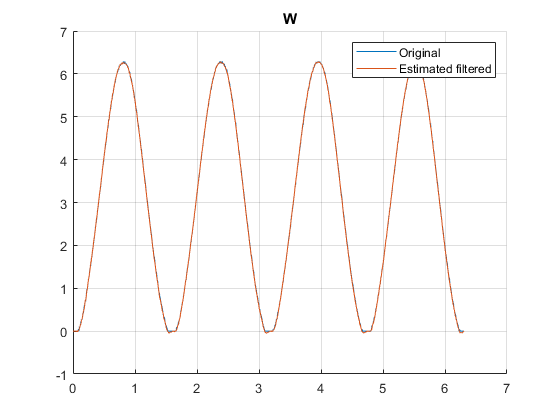

hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")


figure
hold on
plot(time, ddticks_orig)
plot(time, x_arr(2, :), "LineWidth", 2)

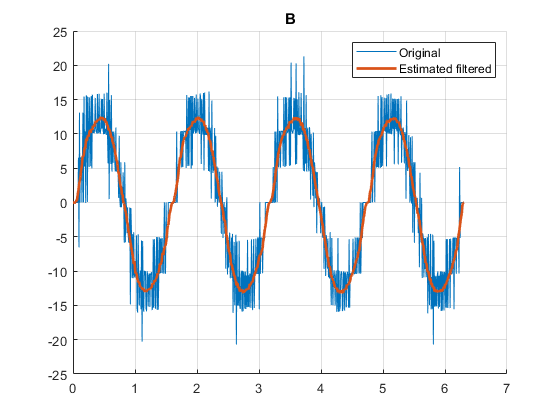

hold off
grid on
title("B")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")


figure
hold on
plot(time, current_orig)
plot(time, x_arr(3, :))

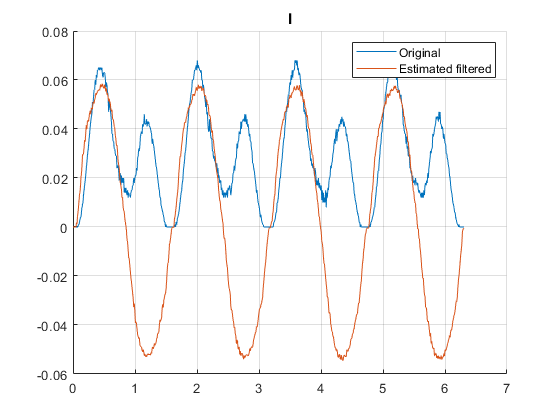

hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

### Parameters identification with kalman filter

% from offline parameter identification
L = 1.9556;
R = 0.6153;
Kw = 1.9952;
Km = 1.9952;
J = 0.0087;
Lam = 0.0022;

% V3
% x = [w dw I]'
% u = u
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L]

A =    -0.2529         0  229.3333
 -233.9772   -0.2529  -72.1563
   -1.0202         0   -0.3146


B = [0 Km/(J*L) 1/L]'

B =          0
  117.2701
    0.5114


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


C_lqe = [1 1 1]

C_lqe =      1     1     1


D = [0 0 0]'

D =      0
     0
     0



[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0012 - 0.0652i  -0.0012 + 0.0652i
   1.0000 + 0.0000i   0.9979 + 0.0000i   0.9979 + 0.0000i
   0.0000 + 0.0000i   0.0043 - 0.0001i   0.0043 + 0.0001i


De =   -0.2529 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2838 +15.2963i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2838 -15.2963i


Cc = ctrb(A,B)

Cc = 1.0e+04 *

         0    0.0117   -0.0067
    0.0117   -0.0067   -2.7410
    0.0001   -0.0000   -0.0120


Cob = obsv(A, C_lqe)

Cob = 1.0e+04 *

    0.0001    0.0001    0.0001
   -0.0235   -0.0000    0.0157
   -0.0041    0.0000   -5.3982


rank(Cc)

ans = 2

rank(Cob)

ans = 3


% best one
% Vd = 0.21 * eye(3) % вера в датчики
% Vn = 0.85 % вера в модель
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов


% Vd = 1e-1 * eye(3)
% Vn = 1

% Vd_w = 1;
% Vd_dw = 1e-2;
% Vd_I = 1e-4;
% Vd = [Vd_w   0    0;
%        0   Vd_dw  0;
%        0     0    Vd_I]
% % Vd = 0.01 * eye(3) % вера в датчики
% Vn = 1 % вера в модель

Vd_w = 40;
Vd_dw = 1;
Vd_I = 1e-3;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];
% Vn = 1
% Vn = [1 0;
%       0 1];
Vn = [1 0 0;
      0 1 0;
      0 0 1];

% C_lqe = [1 0 0]
% C_lqe = [1 0 0;
%          0 1 0];
C_lqe = [1 0 0;
         0 1 0;
         0 0 1];

% [Kf, Pf, Ef] = lqe(A, Vd, C_lqe, Vd, Vn);
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, 0.009);
Kf

Kf =     0.6767   -0.1721   -0.0007
   -0.1721    0.8318    0.0036
   -0.0007    0.0036    0.0000



betta = 2 % коэффициент регуляризации

betta = 2

k0 = 150 % начальное значение матрицы коэффициентов

k0 = 150

% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(5) % диагональная единичная матрица

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


GAMMA_0 = k0.*I % матрица начальных значений коэффициентов

GAMMA_0 =    150     0     0     0     0
     0   150     0     0     0
     0     0   150     0     0
     0     0     0   150     0
     0     0     0     0   150



Th_hat = [0; 0; 0; 0; 0]

Th_hat =      0
     0
     0
     0
     0


Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(3) = Km;
Th_hat(4) = J;
Th_hat(5) = Lam;
Th_hat

Th_hat =     1.9556
    0.6153
    1.9952
    0.0087
    0.0022


dTh_hat = [0; 0; 0; 0; 0]

dTh_hat =      0
     0
     0
     0
     0



G_hat = GAMMA_0

G_hat =    150     0     0     0     0
     0   150     0     0     0
     0     0   150     0     0
     0     0     0   150     0
     0     0     0     0   150


dG_hat = zeros(5,5)

dG_hat =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0



% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);

[Te, De] = eig(A)

Te =    0.0000 + 0.0000i  -0.0012 - 0.0652i  -0.0012 + 0.0652i
   1.0000 + 0.0000i   0.9979 + 0.0000i   0.9979 + 0.0000i
   0.0000 + 0.0000i   0.0043 - 0.0001i   0.0043 + 0.0001i


De =   -0.2529 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2838 +15.2963i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2838 -15.2963i


At = expm(A*dt)

At =     0.9883   -0.0000    2.0516
   -2.0907    0.9977   -2.8085
   -0.0091    0.0000    0.9877


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B

Bt =    0.0047 + 0.0000i
   1.0491 + 0.0000i
   0.0046 + 0.0000i


A_hat = (At-Kf*C_lqe)

A_hat =     0.3116    0.1721    2.0523
   -1.9186    0.1659   -2.8121
   -0.0084   -0.0036    0.9877


B_hat = [Bt Kf]

B_hat =    0.0047 + 0.0000i   0.6767 + 0.0000i  -0.1721 + 0.0000i  -0.0007 + 0.0000i
   1.0491 + 0.0000i  -0.1721 + 0.0000i   0.8318 + 0.0000i   0.0036 + 0.0000i
   0.0046 + 0.0000i  -0.0007 + 0.0000i   0.0036 + 0.0000i   0.0000 + 0.0000i



count = 0;

for k = 2:data_length
% for k = 2:10
    count = count + 1;
    t = time(k);
    dt = time(k) - time(k-1);
    u_act = input(k);
%     I_act = current(k);
%     dI_act = dI(k);
%     w_act = dticks(k);
%     dw_act = ddticks(k);
%     dw_act = ddticks_orig(k);

%     [Te, De] = eig(A);
%     At = expm(A*dt);
%     Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
%     A_hat = (At-Kf*C_lqe);
%     B_hat = [Bt Kf];
%     [Kf, Pf, Ef] = lqe(A, Vd, C_lqe, Vd, Vn);
%     [Kf, Pf, Ef] = lqe(A_hat, Vd, C_lqe, Vd, Vn);
%     [Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);

    u = [input(k-1) (C_lqe*[dticks(k-1) ddticks(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    q_arr(k) = q_arr(k-1) + x_arr(1, k-1)*dt;

    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;
    dI_arr(:, k) = dI_act;
    w_act = x_arr(1, k);
    I_act = x_arr(3, k);
    dw_act = x_arr(2, k);

    phi = [dI_act 0;
           I_act  0;
           w_act -I_act;
           0 dw_act;
           0 w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;

    L = Th_hat(1);
    R = Th_hat(2);
    Kw = Th_hat(3);
    Km = Th_hat(3);
    J = Th_hat(4);
    Lam = Th_hat(5);
    
    A = [-Lam/J        0      Km/J;
         -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
         -Kw/L         0     -R/L];
    B = [0 Km/(J*L) 1/L]';
end

Th_hat;
eL = Th_hat(1)

eL = 1.0554

eR = Th_hat(2)

eR = 5.9076

eKw = Th_hat(3)

eKw = 1.9436

eKm = Th_hat(3)

eKm = 1.9436

eJ = Th_hat(4)

eJ = 0.0085

eLam = Th_hat(5)

eLam = 0.0020

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL]

Ah =    -0.2328  228.8569
   -1.8417   -5.5976


Bh = [-1/eJ 0; 0 1/eL]

Bh =  -117.7465         0
         0    0.9475


C = [1 0; 0 1]

C =      1     0
     0     1


D = [0 0; 0 0]

D =      0     0
     0     0



A = real(Ah)

A =    -0.2328  228.8569
   -1.8417   -5.5976


B = real(Bh)

B =  -117.7465         0
         0    0.9475



Amp = 6;
Bias = 6;
W = 4;
fi = 3.1415;

Const_input = [Amp Bias W fi];

t_f = time(data_length)

t_f = 6.3073

out2 = sim('model', t_f);

### Сравнение графиков мотора с оценочной моделью и фильтром калмана

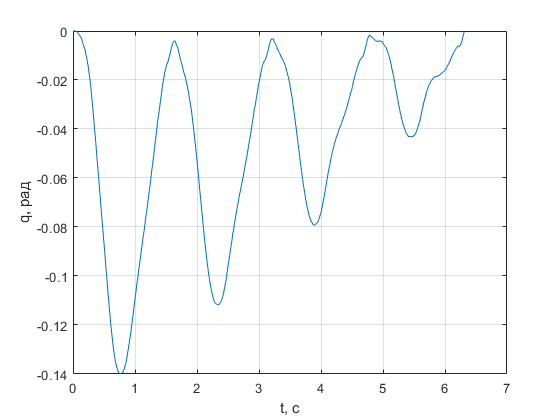

o = out2.simout;

xx = linspace(0, time(data_length), data_length);
q_m = spline(o.q.Time, o.q.Data, xx);
q_err = ticks - q_m';

figure
title("Ошибка по углу")
plot(time, q_err)
xlabel("t, с")
ylabel("q, рад")

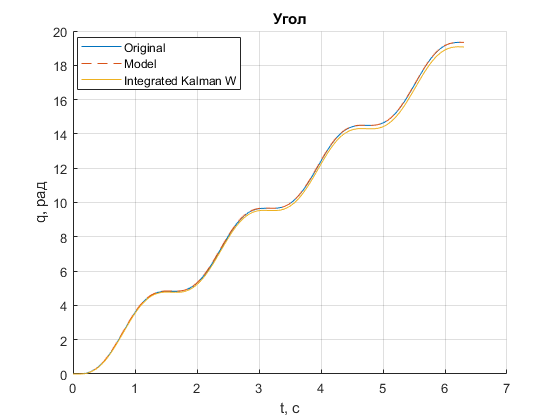


figure
title("Угол")
hold on
plot(time, ticks)
plot(o.q, '--')
plot(time, q_arr)
hold off
xlabel("t, с")
ylabel("q, рад")
legend("Original", "Model", "Integrated Kalman W")
legend("Position",[0.1381,0.78651,0.29286,0.12619])

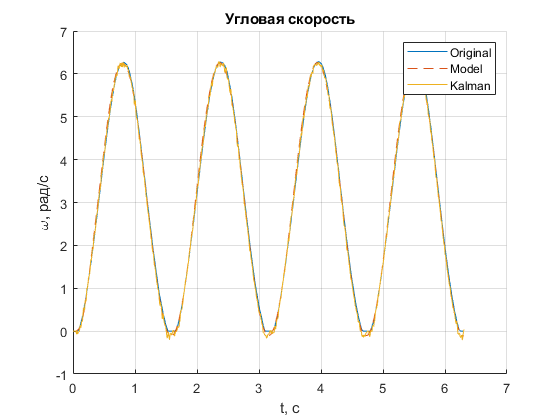


figure
title("Угловая скорость")
hold on
plot(time, dticks)
plot(o.w, '--')
plot(time, x_arr(1, :))
hold off
xlabel("t, с")
ylabel("\omega, рад/с")
legend("Original", "Model", "Kalman")

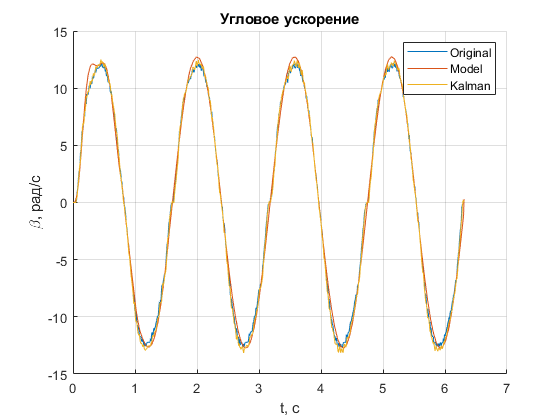


figure
title("Угловое ускорение")
hold on
plot(time, ddticks)
plot(o.dw)
plot(time, x_arr(2, :))
hold off
xlabel("t, с")
ylabel("\beta, рад/с")
legend("Original", "Model", "Kalman")

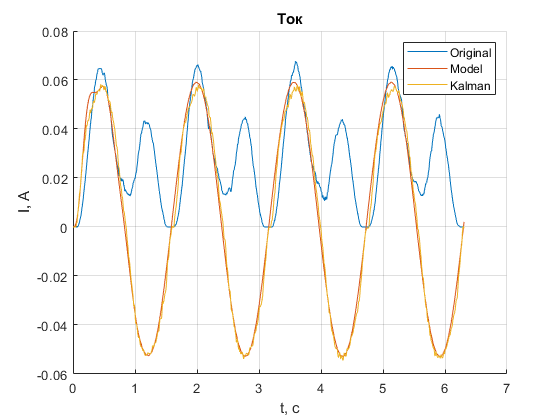


figure
title("Ток")
hold on
plot(time, current)
plot(o.I)
plot(time, x_arr(3, :))
hold off
xlabel("t, с")
ylabel("I, А")
legend("Original", "Model", "Kalman")

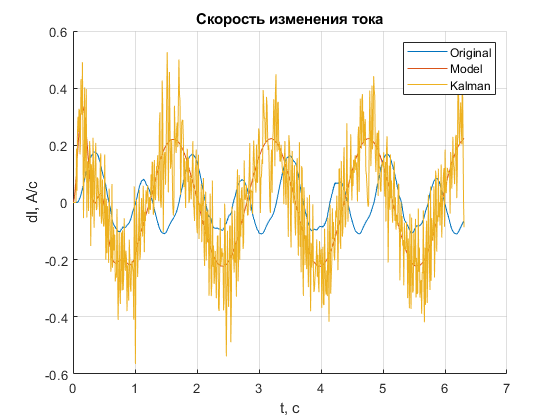


figure
title("Скорость изменения тока")
hold on
plot(time, dI)
plot(o.dI)
plot(time, dI_arr)
hold off
xlabel("t, с")
ylabel("dI, А/c")
legend("Original", "Model", "Kalman")